clear

% y[n] = y[n-1] + TAU*(x[n-1] - y[n-1])

Fs = 127551;
INT_BITS = 2;
FRAC_BITS = 22;
WL = INT_BITS+FRAC_BITS;

% Fs = 10000;     % Sampling Frequency
dt = 1/Fs;
Fn = 440;

R = 1000000;
C = 1*10^-6;
tau = dt/(R*C);

tau_fi = fi(tau,1,WL,FRAC_BITS);
ss = bin(tau_fi)

ss = '000000000000000000100001'

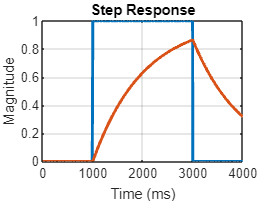




stop = 4*Fs*dt;
t = 0:dt:stop-dt;
N = numel(t);
quarter = floor(N/4);

% Input signal
signal = cos(2*pi*Fn*t);


y = zeros(1,N);
envelope = zeros(1,N);
zero_mask = zeros(1,quarter);
one_mask = ones(1,N-2*quarter);
x = [zero_mask one_mask zero_mask];


for i = 2:N 
    y(i) = y(i-1) + tau*(x(i-1)-y(i-1));
    envelope(i) = signal(i)*y(i);
end

plot(t*(10^3),x, 'LineWidth', 2);
hold on;
plot(t*(10^3),y, 'LineWidth', 2);
xlabel("Time (ms)");
ylabel("Magnitude");
title("Step Response");
grid on;
hold off;

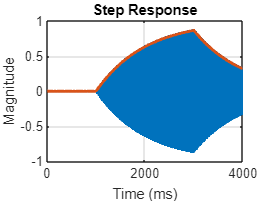


plot(t*(10^3),envelope, 'LineWidth', 2);
hold on;
plot(t*(10^3),y, 'LineWidth', 2);
xlabel("Time (ms)");
ylabel("Magnitude");
title("Step Response");
grid on;
hold off


sound = audioplayer(envelope,Fs);
sound.play



